**Исходная выборка и её преобразование в вариационный ряд**

X=[14.90,14.40,13.56,15.55,13.97,16.33,14.37,13.46,15.51,14.69,13.41,14.24,15.65,14.54,13.55,13.15,14.32,15.04,13.27,14.60,13.83,13.93,14.11,14.15,15.48,15.96,14.46,13.87,13.67,15.30,13.95,16.08,18.25,14.93,15.37,14.38,15.56,13.92,14.23,12.80,13.16,13.89,14.24,13.90,12.82,13.20,13.89,13.50,13.44,16.13,14.68,15.27,13.35,13.62,16.16,16.46,13.83,14.13,15.68,15.22,12.59,12.94,13.09,16.54,14.61,14.63,14.17,13.34,16.74,16.30,13.74,15.02,14.96,15.87,16.03,12.87,14.32,14.48,14.57,14.43,12.61,14.52,15.29,12.07,14.58,11.74,14.97,14.31,12.94,12.82,14.13,14.48,12.25,14.39,15.08,12.87,14.25,15.12,15.35,12.27,14.43,13.85,13.16,16.77,14.47,14.89,14.95,14.55,12.80,15.26,13.32,14.92,13.44,13.48,12.81,15.01,13.19,14.68,14.44,14.89];
X = sort(X)

X =    11.7400   12.0700   12.2500   12.2700   12.5900   12.6100   12.8000   12.8000   12.8100   12.8200   12.8200   12.8700   12.8700   12.9400   12.9400   13.0900   13.1500   13.1600   13.1600   13.1900   13.2000   13.2700   13.3200   13.3400   13.3500   13.4100   13.4400   13.4400   13.4600   13.4800   13.5000   13.5500   13.5600   13.6200   13.6700   13.7400   13.8300   13.8300   13.8500   13.8700   13.8900   13.8900   13.9000   13.9200   13.9300   13.9500   13.9700   14.1100   14.1300   14.1300


**а) Вычисление максимального значения Mmax и минимального значения Mmin**

Xmax = X(end);
Xmin = X(1);

fprintf("Минимальное значение выборки: %f.\n", Xmin);

Минимальное значение выборки: 11.740000.


fprintf("Максимальное значение выборки: %f.\n", Xmax);

Максимальное значение выборки: 18.250000.


**б) Вычисление размаха R выборки**

R = Xmax - Xmin;
fprintf("Размах выборки: %f.\n", R);

Размах выборки: 6.510000.


**в) Вычисление оценок математического ожидания MX и дисперсии DX**

mx = sum(X) / length(X); % выборочное среднее
dx = sum((X - mx).^2) / (length(X) - 1); % несмещённая оценка дисперсии
fprintf("Математическое ожидание X: %f.\n", mx);

Математическое ожидание X: 14.349167.


fprintf("Дисперсия X: %f.\n", dx);

Дисперсия X: 1.277621.


**г) Группировка значений выборки в m = [log2 n] + 2 интервала**

m = floor(log2(length(X))) + 2;
delta = R / m;

borders = Xmin;

for i=2:(m+1)
    borders(i) = borders(i - 1) + delta;
end
function statSeries = CreateSeries(m, borders, X)
    statSeries = zeros(1, m);
    function AddToSeries(val)
      for i=1:(m - 1)
          if (val >= borders(i)) && (val < borders(i+1))
                statSeries(i) = statSeries(i) + 1;
          end
      end
      % Для учёта элементов, равных максимальному
      if (val >= borders(m)) && (val <= borders(m + 1)) 
                statSeries(m) = statSeries(m) + 1;
      end
    end
    arrayfun(@AddToSeries, X)
end
statSeries = CreateSeries(m, borders, X);
check = sum(statSeries) == length(X);
fprintf("Сумма интервального статистического ряда равна объему выборки? : %d.\n", check);

Сумма интервального статистического ряда равна объему выборки? : 1.


out = sprintf("Интервальный статистический ряд: \n");
for i=1:m 
    out = [out, sprintf("[%f;%f) : %d\n", borders(i), borders(i+1), statSeries(i))];
end
disp(join(out, ''))

Интервальный статистический ряд: 
[11.740000;12.553750) : 4
[12.553750;13.367500) : 21
[13.367500;14.181250) : 27
[14.181250;14.995000) : 37
[14.995000;15.808750) : 18
[15.808750;16.622500) : 10
[16.622500;17.436250) : 2
[17.436250;18.250000) : 1



**д) Построение на одной координатной плоскости гистограммы и графика функции плотности распределения вероятностей нормальной случайной величины с математическим ожиданием MX и дисперсией DX**

empirDist = statSeries / (length(X) * delta);
empirDist

empirDist =     0.0410    0.2151    0.2765    0.3789    0.1843    0.1024    0.0205    0.0102


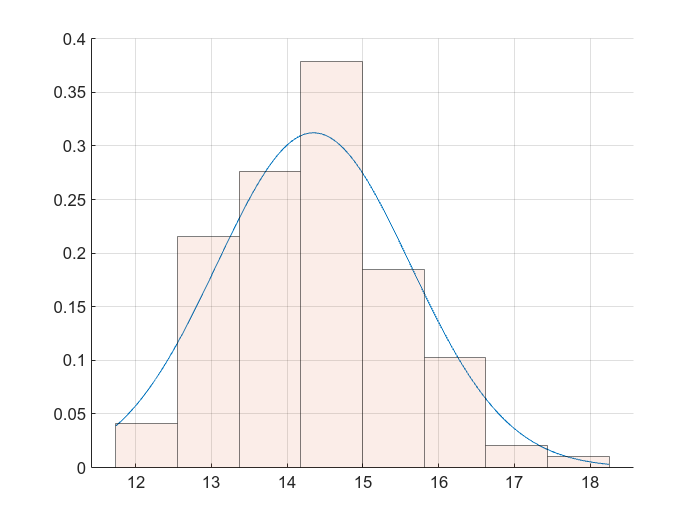

x = Xmin:R/1000:Xmax;
y = normpdf(x, mx, dx);
figure;
hold on
grid on
plot(x, y);
histogram(X, borders, 'Normalization', 'pdf', 'FaceAlpha', 0.1, 'EdgeAlpha', 0.5);
hold off

**е) построение на другой координатной плоскости графика эмпирической функции распределения и функции распределения нормальной случайной величины с математическим ожиданием MX и дисперсией DX**

empirFunc = zeros(1, m);
empirFunc(1) = empirDist(1) * delta;
for i=2:m 
    empirFunc(i) = empirDist(i) * delta + empirFunc(i-1);
end
empirFunc

empirFunc =     0.0333    0.2083    0.4333    0.7417    0.8917    0.9750    0.9917    1.0000


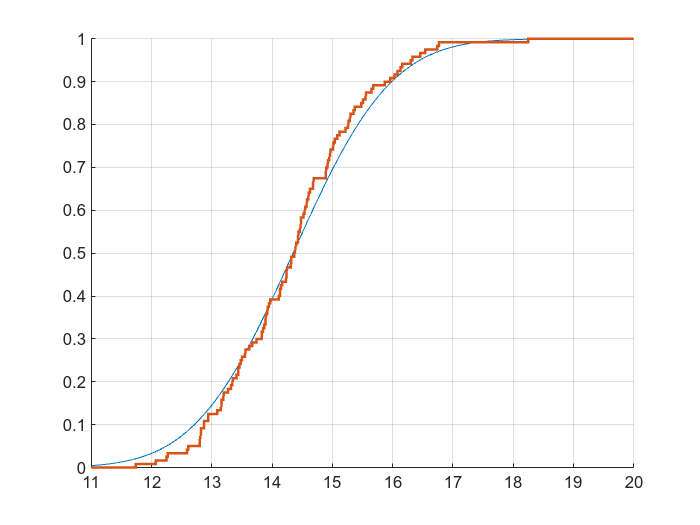

x = 11:R/1000:20;
y = normcdf(x, mx, dx);
figure;
hold on;
grid on;
plot(x, y);

[uniqX, ~, ind] = unique(X);
cntX = accumarray(ind, 1);
cumcntX = cumsum(cntX);
edX = cumcntX / length(X);
stairs([11; uniqX(:); 20], [0; edX(:); 1], 'LineWidth', 1.5);


hold off;